# Initialize

clear all;
gamma = 5/3;
kUpLimit = -0.01;
k_horizontal_1 = -2:0.01:kUpLimit;
k_vertical_1 = -2:0.01:kUpLimit;
% alpha = 0:1:90;
% k_vertical_1 = (tand(alpha))'*k_horizontal_1;
w1= solve_wave_dispersion(k_horizontal_1,k_vertical_1,gamma);


## Plotting

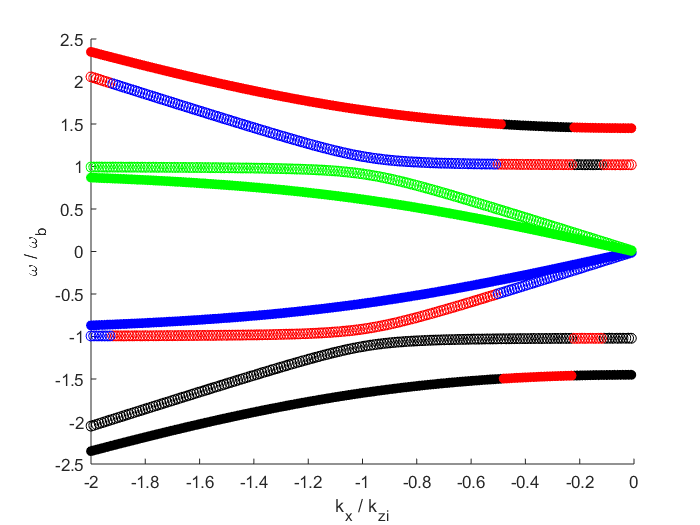

figure;
scatter(k_horizontal_1,squeeze(w1(:,end,1)),'k');
hold on;
scatter(k_horizontal_1,squeeze(w1(:,end,2)),'r');
scatter(k_horizontal_1,squeeze(w1(:,end,3)),'b');
scatter(k_horizontal_1,squeeze(w1(:,end,4)),'g');
scatter(k_horizontal_1,squeeze(w1(:,100,1)),'k','filled','o');
scatter(k_horizontal_1,squeeze(w1(:,100,2)),'r','filled','o');
scatter(k_horizontal_1,squeeze(w1(:,100,3)),'b','filled','o');
scatter(k_horizontal_1,squeeze(w1(:,100,4)),'g','filled','o');
% ylim([0 2]);
xlabel('k_x / k_z_i');
ylabel('\omega / \omega_b')

## MSIS

m = 28.9 * 1.67*10^-27; %kg
kb = 1.38064852 * 10^-23; %  m2 kg s-2 K-1
g0 =  9.80665 ; % m/s^2
re = 6.3781 *10^6; % m
time = datenum('21 Aug 2017 12:00');
lat = 50;
lon = -100;
altitude = 1:1:300;
[Density, Temperature] = msis(time,lat,lon,altitude);
TN = Temperature(:,1);
cs = (gamma.*kb.*TN./m).^0.5;
g = (g0.*(re./(re+altitude*1000)).^2)';


## Plot & Check MSIS

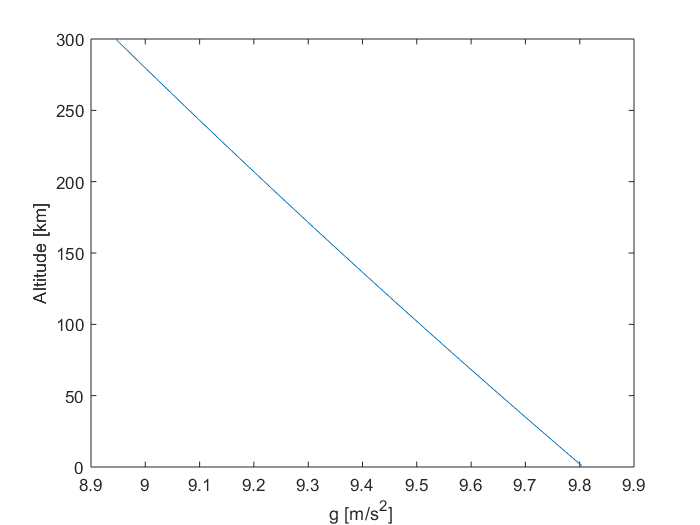

figure;
plot(g,altitude); xlabel('g [m/s^2]'); ylabel('Altitude [km]');

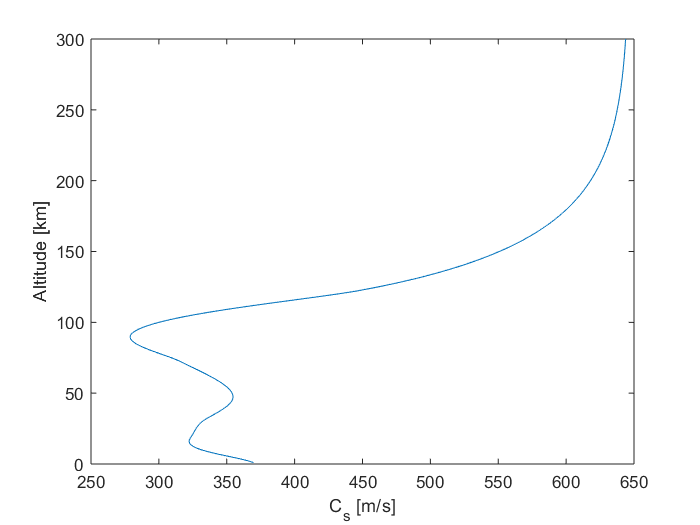

figure;
plot(cs,altitude); xlabel('C_s [m/s]'); ylabel('Altitude [km]');

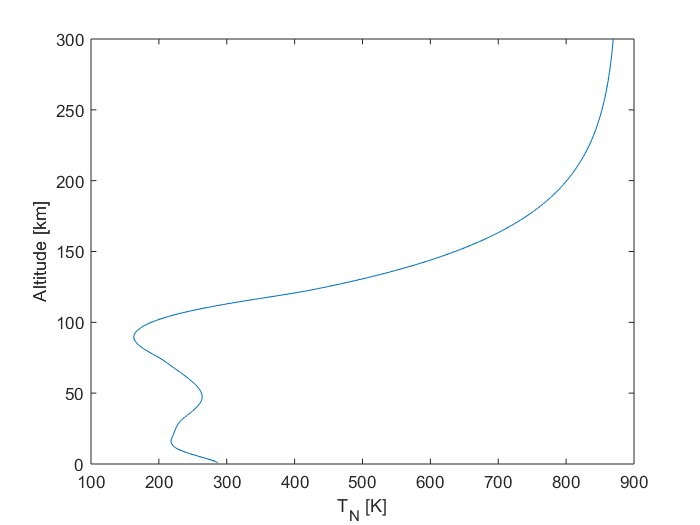

figure;
plot(TN,altitude); xlabel('T_N [K]'); ylabel('Altitude [km]');

## Calculating w and k

ans = 0.0223

ans = 0.0143

ans = 0.0142

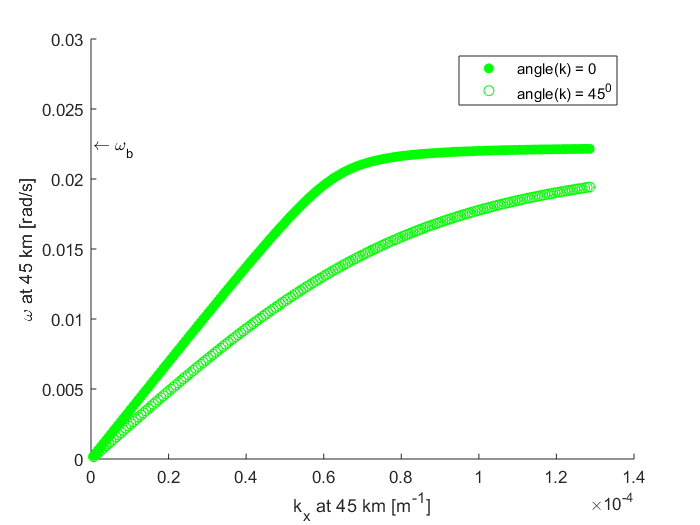

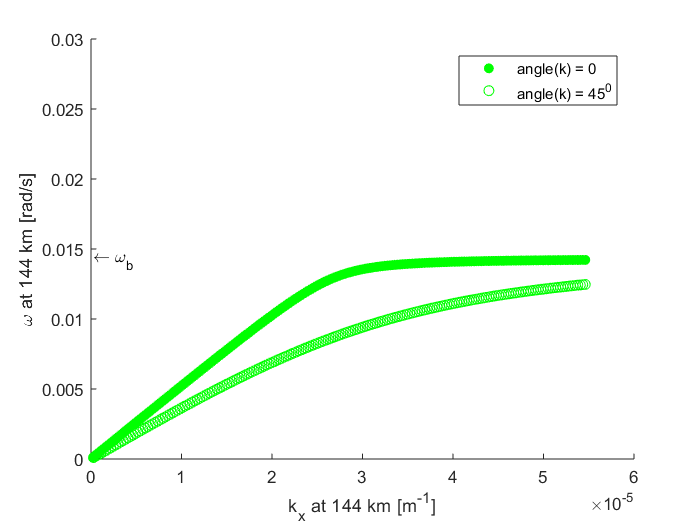

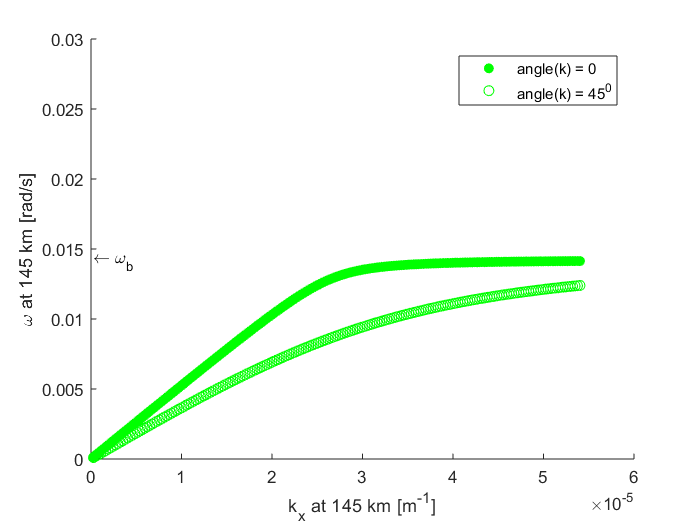

alt=[45,144,145];
for i = 1:3
pick_alt = alt(i);
rootNo = 4;

kzr_index_0 = find(k_vertical_1==kUpLimit); % No vertical component for k
kzr_index_1 = find(k_vertical_1==-1); % k inclined 45 deg. to horizontal
kzi = -gamma.*g./(2.*cs.^2);
wb = (((gamma-1).*g.^2)./(cs.^2)).^0.5;

% For Kz = 0 & Alt = 45;
[val,altIndx]=(min(abs(altitude-pick_alt)));
w = w1(:,kzr_index_0,rootNo).*wb(altIndx);
w_k_45 = w1(:,kzr_index_1,rootNo).*wb(altIndx);
k_horizontal = k_horizontal_1.*kzi(altIndx);
k_vertical = k_vertical_1.*kzi(altIndx);

% 
% figure;
% plot(wb,altitude); xlabel('\omega_b [Hz]'); ylabel('Altitude [km]');
% figure;
% plot(kzi,altitude); xlabel('img(k_z) [m^-1^]'); ylabel('Altitude [km]');

figure;
scatter(k_horizontal,w,'g','filled','o');
hold on;
scatter(k_horizontal,w_k_45,'g');
legend ('angle(k) = 0','angle(k) = 45^0');
hold on;
text(min(k_horizontal),wb(altIndx),'\leftarrow \omega_b');
wb(altIndx)
% line(k_horizontal_1,wb(altIndx)*ones(length(k_horizontal_1)));
ylim([0 0.03]);
ylabel(['\omega at ',num2str(pick_alt),' km [rad/s]']);
xlabel(['k_x at ',num2str(pick_alt),' km [m^-^1]']);
end

## Calculating k variation given an w

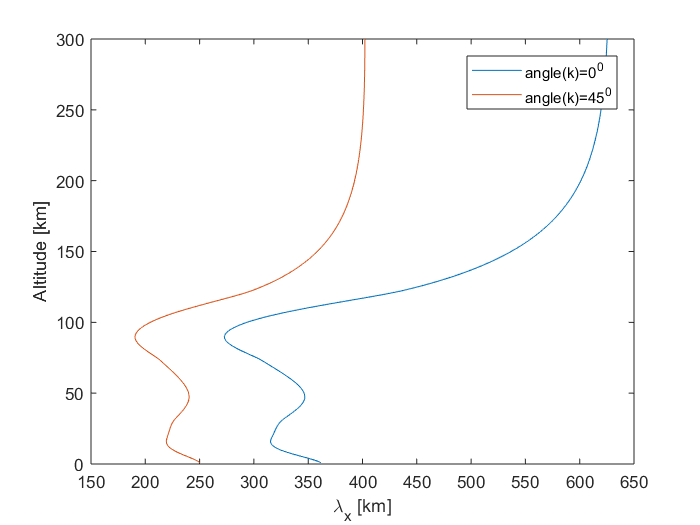

f = 1*10^-3; %1 mHz
% f = 3.4*10^-5;
w_given = 2*pi*f;
rootNo = 4;
kzi = -gamma.*g./(2.*cs.^2);
wb = (((gamma-1).*g.^2)./(cs.^2)).^0.5;
    
for i=1:1:length(altitude)
    pick_alt=altitude(i);
    kzr_index_0 = find(k_vertical_1==kUpLimit); % No vertical component for k
    kzr_index_1 = find(k_vertical_1==-1); % k inclined 45 deg. to horizontal
    [val,altIndx]=(min(abs(altitude-pick_alt)));
    k_horiz(i) = interp1(w1(:,kzr_index_0,rootNo).*wb(altIndx),k_horizontal_1.*kzi(altIndx),w_given);
    k_horiz_45(i) = interp1(w1(:,kzr_index_1,rootNo).*wb(altIndx),k_horizontal_1.*kzi(altIndx),w_given);
%     [w(i),wIndx] =  min(abs(w1(:,kzr_index_0,rootNo).*wb(altIndx)-w_given));
%     [w_k_45(i),w_k_45_Indx] =  min(abs(w1(:,kzr_index_1,rootNo).*wb(altIndx)-w_given));
%     k_horizontal(i) = k_horizontal_1(wIndx).*kzi(altIndx);
%     k_horizontal_45(i) = k_horizontal_1(w_k_45_Indx).*kzi(altIndx);
end

figure;
lambda = 2*pi./k_horiz;
lambda_45 = 2*pi./k_horiz_45;
plot(lambda/1000,altitude);
hold on;
plot(lambda_45/1000,altitude);
xlabel('\lambda_x [km]');
ylabel('Altitude [km]');
legend('angle(k)=0^0','angle(k)=45^0')

**Functions **

function w=solve_wave_dispersion(kx,kzr,gamma)
    alpha = (gamma.^2)./(4*(gamma-1));
    n_kx = length(kx);
    n_kzr = length(kzr);
    for i = 1:1:n_kx
        for j = 1:1:n_kzr
            w(i,j,:) =...
                roots([1,... %w4
                       0,... %w3
                       -alpha.*(kx(i).^2+kzr(j).^2+1),... %w2
                       0,... %w1
                       alpha.*kx(i).^2]); %w0
        end
    end
  
end

function w=solve_wave_dispersion_theta(kx,theta,gamma)
    alpha = (gamma.^2)./(4*(gamma-1));
    n_kx = length(kx);
    kzr = (tand(theta))*kx;
    for i = 1:1:n_kx
           w(i,i,:) =...
                roots([1,... %w4
                       0,... %w3
                       -alpha.*(kx(i).^2+kzr(i).^2+1),... %w2
                       0,... %w1
                       alpha.*kx(i).^2]); %w0
    end
  
end

